# 2. Register Doppler volume using that of angiogram.

Dock figure(1) to use [this layout](https://docs.google.com/document/d/1RuEO2t5K-t82QPUK-sShLjorJyRC5uLGxchojfOiYDs/edit#heading=h.3m49wo5vra7y) BEFORE running the first session.  Clear all output.

## 20. Initiate.

Select a set of *eid's* or *pid*'s to load. 

- aid : Analysis ID (results from this analysis will be saved by this file name)

- aidA : Analysis ID of "Register MIP" of the corresponding angiogram.

comInit;

aid = 'ad6-doppler-test';  % Analysis ID

uid = 'kwalek';  % User ID
ceid = {'170914_AD6', '171007_AD6', '171104_AD6', '171118_AD6', '171211_AD6', '180122_AD6', '180223_AD6'};  % Experiment ID list
cpid = {'dop-AD6-1', 'dop-AD6-2', 'dop-AD6-3', 'dop-AD6-4', 'dop-AD6-5', 'dop-AD6-6', 'dop-AD6-7'};  % Process ID list

uidA = 'kwalek';
aidA = 'ang-AD6-1';  % "aid" you used in /Angiogram/2 Register MIP.mlx

uid = 'jang';  % User ID
% ADS1
ceid = {'180611 ADS1', '180713 ADS1', '180806 ADS1', '180903 ADS1', '181210 ADS1', '190114 ADS1'};  % Experiment ID list
cpid = {'dop-ADS1-3', 'dop-ADS1-4','dop-ADS1-5','dop-ADS1-6','dop-ADS1-9','dop-ADS1-10'};  % Process ID list
uidA = 'jang';
aidA = 'angio-ADS1-coMIPr';  % "aid" you used in /Angiogram/2 Register MIP.mlx

ceid = {'180627_ADS4', '180718_ADS4', '180808_ADS4', '180907_ADS4', '181213_ADS4', '190114_ADS4', '190211_ADS4','190506_ADS4'};  % Experiment ID list
cpid = {'dop-ADS4-3', 'dop-ADS4-4','dop-ADS4-5','dop-ADS4-6','dop-ADS4-9','dop-ADS4-10','dop-ADS4-11','dop-ADS4-14'};  % Process ID list
uidA = 'jang';
aidA = 'angio-ADS4-coMIPr';  % "aid" you used in /Angiogram/2 Register MIP.mlx

pathdata = ['D:\' uid '\'];  % path to save the analysis result
pathrepo = ['R:/ENG_Lee-Lab_Shared/group/report/ad-16-ko-mouse/Doppler/2 Register Doppler # ' uid ' # ' aid];  % path of report figures

sec20;

INIT COMPLETED.


## 21. Load Doppler data.

sec21;

SECTION 21 RUNNING ...
14:14 data loaded 1/8
14:14 data loaded 2/8
14:14 data loaded 3/8
14:15 data loaded 4/8
14:15 data loaded 5/8
14:15 data loaded 6/8
14:16 data loaded 7/8
14:16 data loaded 8/8
SECTION 21 COMPLETED.


## 22. Navigate *en face *slices and set the representative depth of each.

Set parameters and run this section.  Values in the instruction below means default. 

- dz = 5 : The number of voxels to move in depth.

- zavg = 2 : The number of *en face *slices to be averaged.  +/-zavg slices will be averaged.

- limV = 5*[-1 1] : The color range of the velocity [mm/s]

UI keys

- Q: Quit.

- G: Select a depth manually.

- E/D: Decrease/increase the depth of monitoring.

- S/F: Move to the previous/next session.

Tip: When measuring flow in *3 Track flow.mlx*, it is better to choose a depth where most vessels appear circular (left).  However, in this registration, it is better to choose depths so that you can see structural features like the specific Y-branch below across sessions (center, right).  It will help you see how well the registration works in the following section.

    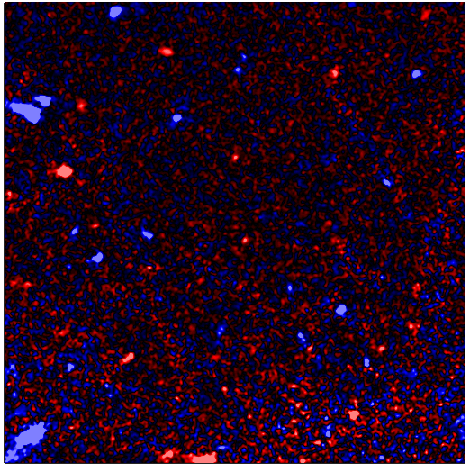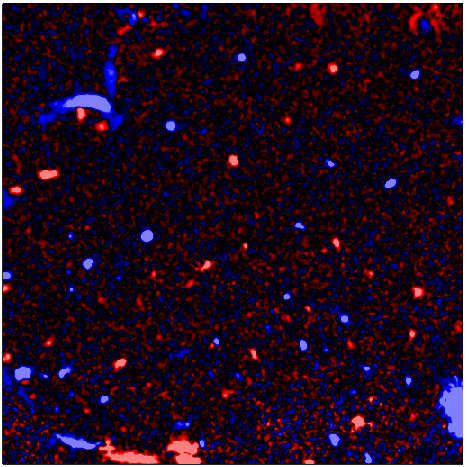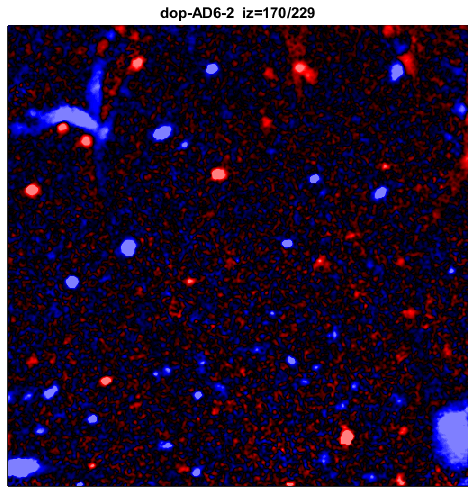

SECTION 22 RUNNING ...


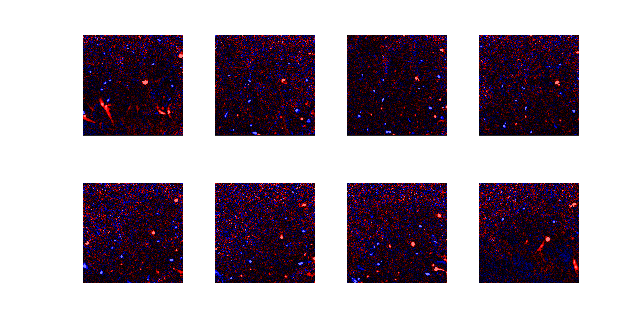

SECTION 22 COMPLETED.


dz = 5;
zavg = 2;
limV = 5*[-1 1];

sec22;

## 23. Register

- ap.bSkip = false : Whether to skip the registration.  No registration when ap.bSkip = true or you skipped the registration of angiograms.

SECTION 23 RUNNING ...
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).


SECTION 23 COMPLETED.


ap.bSkip = true;

sec23;

## 24. Find the common ROI (automatically).

If all three options (oini = 1, 2, 3) fail, move to Sec 24a for manual selection.  If one of them succeeded, skip Sec 24a.

Run this section even when you selected ap.bSkip = true in Section 23.  This section will set the common ROI to be the whole FOV.  In this case, please skip Sec. 24a. 

- ap.oini = 3 : An option to generate the initial guess for the optimization FindMaxRect().  Choose from 1-3.

ap.oini = 3;

sec24;

SECTION 24 RUNNING ...


SECTION 24 COMPLETED.


### 24a. Find the common ROI (manually).

UI keys

- Q: Quit

- G: Select an ROI.

SECTION 24a RUNNING ...


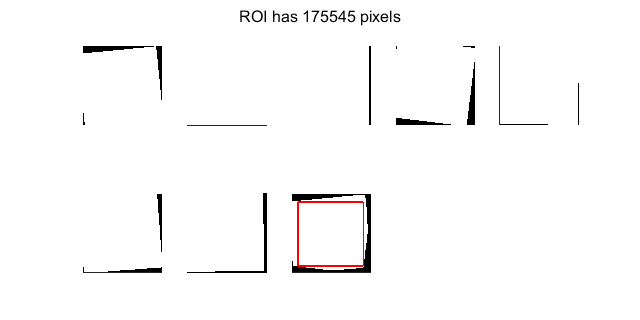

SECTION 24a COMPLETED.


sec24a;

## 25. Crop the volume data for the common ROI.

SECTION 25 RUNNING ...


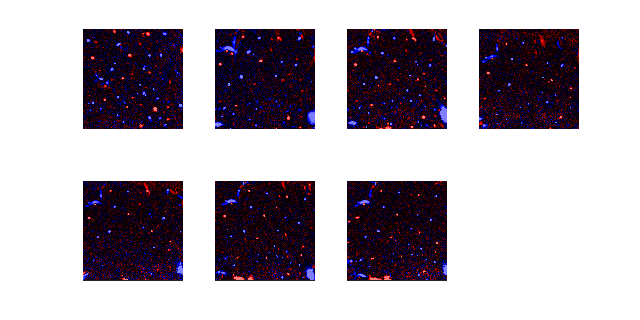

SECTION 25 COMPLETED.


sec25;

**Check points:**

- Compare this result to the figure of Sec 22.  Do you see the effect of registration (e.g., the structural feature appears in the same locations)?

## 29. Save.

fpath = [pathdata aid '.mat'];
if ~isempty(dir(fpath))
    disp('Overwriting ...');
else
    disp('Saving ...');
end

Saving ...


for id=1:nd
    cVV{id} = cVV{id}(:,ap.xx,ap.yy);
end
clear cVV0 VV Vc;
save('-v7.3',fpath);
disp('Analysis saved');

Analysis saved
